# Ejercicio 1

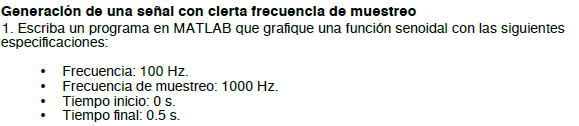

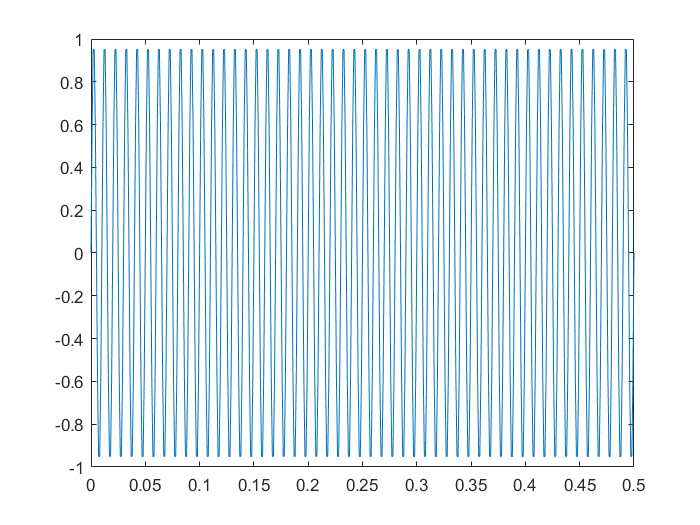

f=100;
fs=1000;
t0=0;
tf=0.5;

dt=1/fs;
t_vec=t0:dt:tf;
vec_sen=sin(t_vec*f*2*pi);
plot(t_vec,vec_sen);

# Ejercicio 2

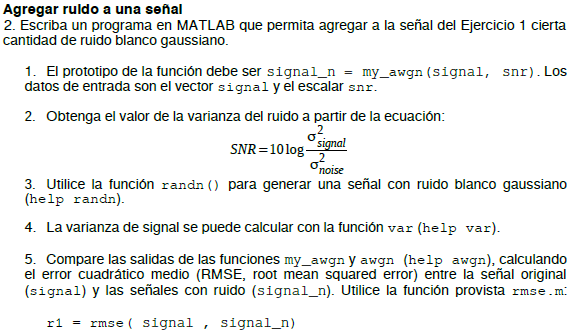

### Despeje ec varianza del ruido

## 
$${\sigma_{\textrm{noise}} }^2 =\frac{{\sigma_{\textrm{signal}} }^2 }{{10}^{\frac{\textrm{SNR}}{10}} }$$


vec_sen

vec_sen =          0    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878   -0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878


snr=15

snr = 15

signal_with_my_noise=my_awgn(vec_sen,snr) %(5)

signal_with_my_noise =     0.0676    0.8184    0.6670    1.0595    0.6279   -0.1644   -0.6423   -0.9080   -0.5011   -0.2395   -0.1697    0.9694    1.0423    0.9431    0.6777   -0.0258   -0.6034   -0.7637   -0.7739   -0.4096    0.0844    0.4360    1.0412    1.1560    0.6493    0.1301   -0.4964   -0.9892   -0.9141   -0.6868    0.1117    0.4435    0.8167    0.8493    0.2176    0.1809   -0.5469   -1.0460   -0.7788   -0.8030   -0.0129    0.5574    0.9912    0.9904    0.4790   -0.0038   -0.6085   -0.8721   -0.8136   -0.4483


signal_with_matlab_noise=awgn(vec_sen,snr)

'awgn' requires Communications Toolbox.

my_noise_rmse=rmse(vec_sen,signal_with_my_noise)
matlab_noise_rmse=rmse(vec_sen,signal_with_matlab_noise)

### Plot to verify diferences

figure(2)
limit=101;
plot(t_vec(1:limit),vec_sen(1:limit),'r')
hold on
plot(t_vec(1:limit),signal_with_my_noise(1:limit),'b')
plot(t_vec(1:limit),signal_with_matlab_noise(1:limit),'m')

function signal_n=my_awgn(signal,snr) %(1)
    var_signal=var(signal); %(4)
    var_noise=var_signal/(10^(snr/10));%(2)
    
    n=length(signal);
    noise=sqrt(var_noise).*randn(1,n); %(3)   mu=0; std_dev=sqrt(var_noise)
    signal_n=signal+noise;   
end